# Align Table Entry Content Horizontally

This example shows how to specify the horizontal alignment of table entries in DOM API informal and formal tables. The example shows how to set the alignment of all table entries, the entries in a row, and an individual entry.

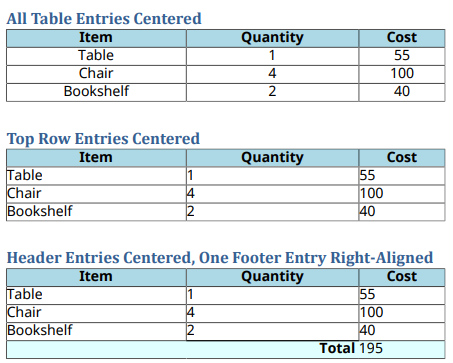

## Document and Data Setup

Import the DOM package so that you do not have to use long, fully qualified class names. 

import mlreportgen.dom.*

Create and open a a PDF document. To create a Word document instead, change the output type from `pdf` to `docx`. To create an HTML document instead, change `pdf` to `html` or `html-file` for a multi-file or single-file document, respectively.

d = Document("mydoc","pdf");
open(d);

Define the styles for the table, header row, and footer row.

tableStyle = { Width("80%"), ...
               Border("solid"), ...
               RowSep("solid"), ...
               ColSep("solid") };

headerStyle = { BackgroundColor("LightBlue"), ...
                Bold(true) };

footerStyle = { BackgroundColor("LightCyan"), ...
                ColSep("none"), ...
                WhiteSpace("preserve") };

Define content for the table header row, body, and footer row. 

headerContent = {'Item', 'Quantity', 'Cost'};
bodyContent = {'Table', 1, 55; ...
               'Chair', 4, 100; ...
               'Bookshelf', 2, 40};

total = sum([bodyContent{:,3}]);
footerContent = {[],'Total ',total};

tableContent = [headerContent; bodyContent];

## Set Alignment of All Table Entries

For the first table, center all of the table entries by setting a single table property.

Create an `mlreportgen.dom.Table` object using the previously defined content. Assign styles to the table and the first row of the table.

append(d,Heading1("All Table Entries Centered"));

table = Table(tableContent);
table.Style = tableStyle;

firstRow = table.Children(1);
firstRow.Style = headerStyle;

Set the horizontal alignment of all table entries by setting the `TableEntriesHAlign` property to `"center"`. Append the table to the document.

table.TableEntriesHAlign = "center";
append(d, table);

## Set Alignment of Entries in a Table Row

For the next table, center only the top row table entries by modifying the row `Style` property.

Assign styles to the table and the first row of the table. Instead of setting the horizontal alignment with the `TableEntriesHAlign` property, create an `HAlign` object and include it in the `Style` property of the first row along with the header style defined previously. 

append(d,Heading1("Top Row Entries Centered"));

table = Table(tableContent);
table.Style = tableStyle;

firstRow = table.Children(1);
firstRow.Style = [{HAlign("center")},headerStyle];

append(d,table);

The alignment defined for a table row by the `Style` property of the table row overrides the alignment defined for the entire table by the `TableEntriesHAlign` property.

## Set Alignment of a Formal Table Header and a Single Entry in the Footer

For the last table, ceate a formal table using an `mlreportgen.dom.FormalTable` object. Center the table header entries and align a single footer entry to the right.

Create an `mlreportgen.dom.FormalTable` object. Set the styles of the overall table, header, and footer. Because the header of a `FormalTable` object is separate from the body, you can set the alignment of the header entries by using the `TableEntriesHAlign` property without affecting the body or footer entries. Alternatively, you can add an `HAlign` object to the row `Style` property.

append(d, Heading1("Header Entries Centered, One Footer Entry Right-Aligned"));

table = FormalTable(headerContent,bodyContent,footerContent);
table.Style = tableStyle;

table.Header.TableEntriesHAlign = "center";
table.Header.Style = headerStyle;

footer = table.Footer;
footer.Style = footerStyle;

Align the second entry of the footer to the right by including an `HAlign` object in the `Style` property of the entry. Make the entry bold by adding an `mlreportgen.dom.Bold` object.

totalEntry = entry(footer,1,2);
totalEntry.Style = {HAlign("right"),Bold(true)};

append(d,table);

Close and view the document.

close(d);
rptview(d);

*Copyright 2018 The MathWorks, Inc.*